# Transmit Signal

Scenario : We will send a pulse that has a bandwidth of B

#### Transmit siganl $p\left(t\right)=e^{\frac{j\pi 0\ldotp 25\mathrm{MHz}}{0\ldotp 2\mathrm{ms}}t^2 }$

tau = 0.2;
B=0.25e6;
pt =@(t) exp(j.*(pi.*B.*t.^2./tau + 2*pi*0.5e6*t));
x = [-0.2:0.01:0.2];
y = pt(x);
size(x)

ans =      1    41


a= abs(fft(y)); b = conj(a);

### $X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\mathrm{j2}\pi \frac{\mathrm{nk}}{N}}$  so How does matlab knows N ? of course Length of the vector !!

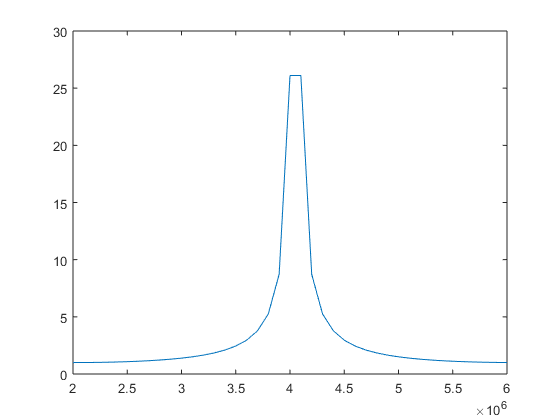

plot(2e6:0.1e6:(2e6)+0.1e6*40,a)

plot(2e6:0.1e6:(2e6)+0.1e6*40,b)